# MTH 4800 Numerical Analysis I Homework 10

## Jarred Maestas

    1. What assumptions should be made to guarantee convergence of the power method?

        - For the Power Method to guarantee convergence to the dominant eigenvalue, the matrix $A$ must be a square $n \times n$ matrix. Second, matrix $A$ must possess $n$ distinct eigenvalues where the largest eigenvalue is unique in magnitude, specifically satisfying $|\lambda ₁| > |\lambda ₂| \ge  |\lambda ₃| \ge  ... \ge  |\lambda ₙ|$. This uniqueness of the dominant eigenvalue is important because the convergence rate depends on the ratio $|\frac{\lambda ₂}{\lambda ₁}|$, and without a strictly dominant eigenvalue, the method may converge to multiple eigenvalues simultaneously or fail to converge entirely.

        Third, there must exist $n$ linearly independent eigenvectors $\{v⁽¹⁾, v⁽²⁾, ..., v⁽ⁿ⁾\}$ corresponding to these eigenvalues. While matrices with repeated eigenvalues may still allow convergence in some cases, the existence of a complete set of linearly independent eigenvectors is required to guarantee theoretical convergence. Lastly, any initial vector $x⁽⁰⁾$ in $Rⁿ$ must be expressible as a linear combination of these eigenvectors, meaning $x⁽⁰⁾ = \Sigma ⱼ₌₁ⁿ \beta ⱼv⁽ʲ⁾$, where $\beta ₁ \not=  0$. This last condition ensures that the initial guess has a nonzero component in the direction of the dominant eigenvector. If $\beta ₁ = 0$, the method will converge to a different eigenvalue or fail. 

    2. Walk through the derivation in the notes, and explain in a few sentences what is happening that causes the Power Method to converge to the largest eigenvalue and its associated eigenvector.

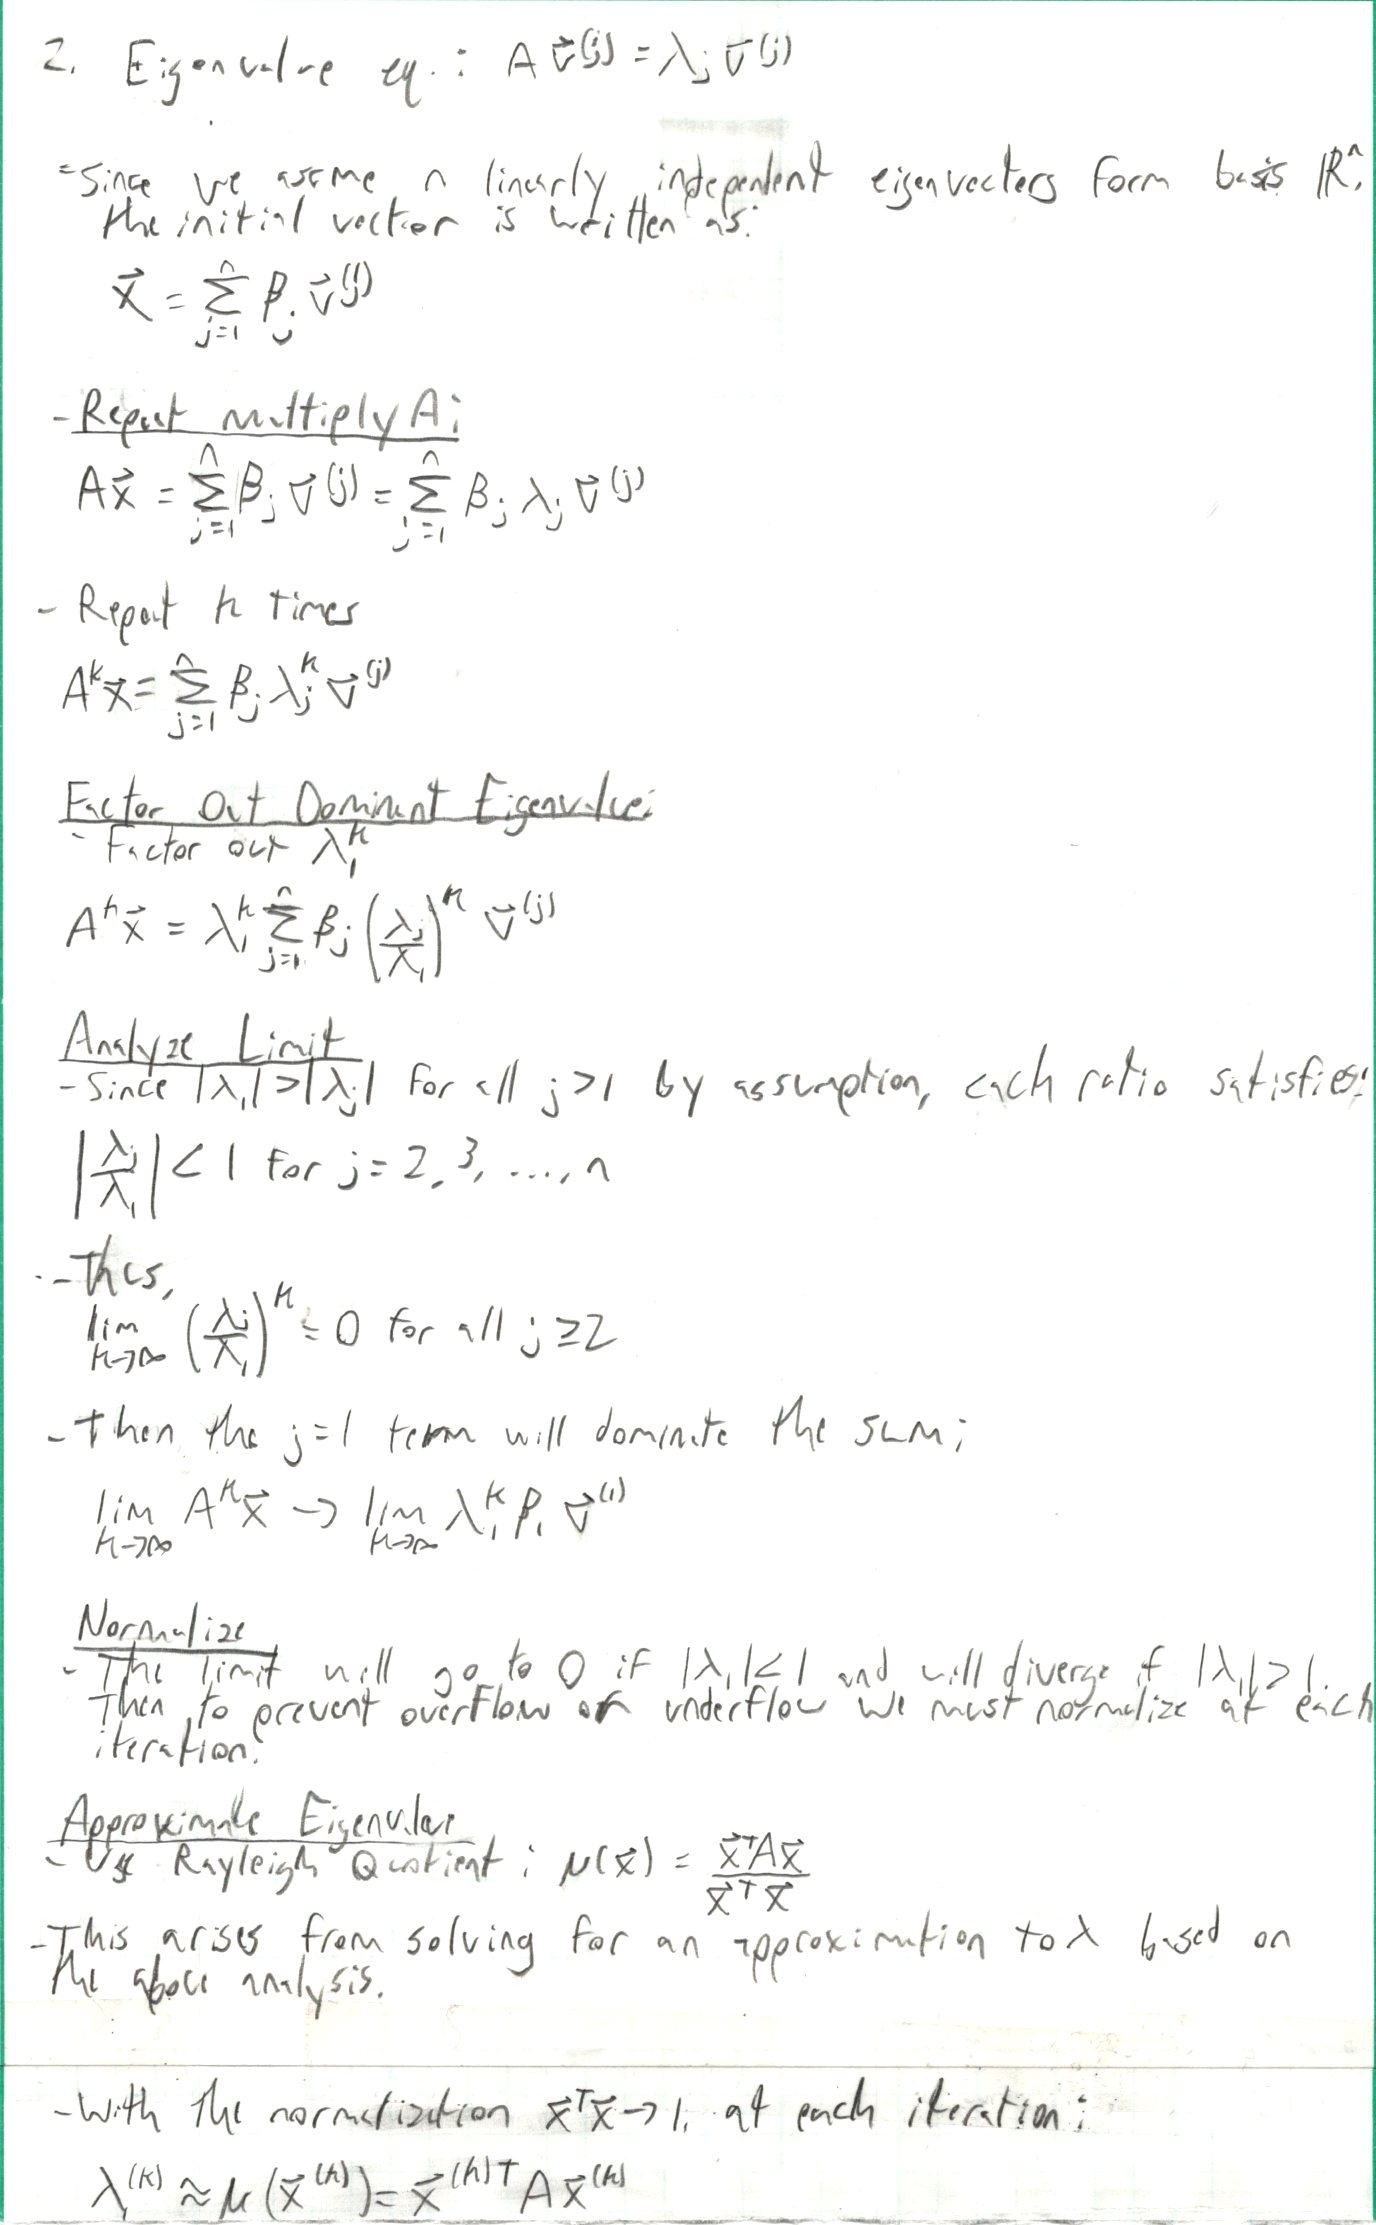

        - The Power Method works by exploiting the fact that repeated matrix multiplication amplifies components in the direction of the dominant eigenvector while exponentially suppressing all other components. When we factor out $\lambda _1^k$� from $A^k\vec{x}$, all the ratios $(\frac{\lambda _j}{\lambda _1})^k$  for $j\ge 2j$ decay to zero since each ratio is less than 1 in magnitude, leaving only the dominant eigenvector component $\beta _1\vec{v}^{(1)}$. Normalization at each step prevents numerical overflow/underflow while allowing the normalized vectors to converge to the dominant eigenvector, and the Rayleigh quotient extracts the corresponding eigenvalue. The convergence rate is linear with the rate $|\frac{\lambda _2}{\lambda _1}|$, determined by how quickly the second-largest eigenvalue component decays relative to the dominant one.

    3. What is a Rayleigh quotient and how can it be used for eigenvalue computations?

        - The Rayleigh quotient is a scalar function defined for a matrix $A$ and $\vec{x}$ as $\mu (x) = \frac{xᵀAx}{xᵀx}$, which provides an approximation to an eigenvalue of $A$. This quotient comes from the eigenvalue equation $A\vec{x} = \lambda \vec{x}$ by taking the inner product of both sides with $\vec{x}$, yielding $\vec{x}ᵀA\vec{x} = \lambda \vec{x}ᵀ\vec{x}$, and solving for $\lambda $. When $\vec{x}$ is equal to an eigenvector corresponding to eigenvalue λ, the Rayleigh quotient returns that eigenvalue. When $\vec{x}$ is an approximation to an eigenvector, the Rayleigh quotient provides the best scalar approximation to the corresponding eigenvalue as least-squares.

    In eigenvalue computations, like in the Power Method, the Rayleigh quotient is used at each iteration to extract an eigenvalue approximation from the current eigenvector approximation. After normalizing the vector $\vec{x}⁽ᵏ⁾$ so that $\vec{x⁽ᵏ⁾ᵀ}\vec{x⁽ᵏ⁾} = 1$, the Rayleigh quotient simplifies to $\mu (\vec{x⁽ᵏ⁾}) = \vec{x⁽ᵏ⁾ᵀ}A\vec{x⁽ᵏ⁾}$, which converges to the dominant eigenvalue $\lambda ₁$ as $\vec{x⁽ᵏ⁾}$ converges to the dominant eigenvector. The Rayleigh quotient is valuable because it provides an eigenvalue approximation that is typically more accurate than the eigenvector approximation itself. For symmetric matrices, the convergence rate of the Rayleigh quotient to the eigenvalue is $O(|\frac{\lambda ₂}{\lambda ₁}|²ᵏ)$, which ihas a quadratic convergence rate of the eigenvector making it more efficient for symmetric eigenvalue problems.

    4. What is the singular value decomposition (SVD)?

        - The SVD is a matrix factorization technique that decomposes any $m \times n$ matrix $A$ into the product of three matrices, $A = U\Sigma Vᵀ$. In this decomposition, $U$ is an $m \times m$ orthogonal matrix whose columns are the left singular vectors of $A$, $\Sigma $ is an $m \times n$ diagonal matrix containing the singular values $\sigma ₁ \ge  \sigma ₂ \ge  ... \ge  \sigma ᵣ \ge  0$, arranged in descending order along the diagonal, and $Vᵀ$ is the transpose of an $n \times n$ orthogonal matrix $V$ whose columns are the right singular vectors of $A$.

    The singular values in $\Sigma $ are connected to eigenvalues through the relationship $AᵀA = V\Sigma ᵀUᵀU\Sigma Vᵀ = V\Sigma ᵀ\Sigma Vᵀ = V\Sigma ²Vᵀ$, demonstrating that the singular values of $A$ are the square roots of the eigenvalues of the square matrix $AᵀA$. For non-square or singular matrices where regular eigenvalue methods fail, SVD provides a way to find these generalized eigenvalues and solve linear systems. The decomposition allows solving $A\vec{x} = \vec{b}$ even for non-square $A$ by reformulating as $x = V\Sigma ⁻¹Uᵀb$, where $\Sigma ⁻¹$ involves taking reciprocals of nonzero singular values. 

    5. What is the connection between singular values and the spectral condition number, $\kappa ₂(A)$?

        - The spectral condition number $\kappa ₂(A)$ measures the sensitivity of a linear system $A\vec{x} = \vec{b}$ to perturbations in the data, and it is defined as the ratio of the largest to smallest singular values of $A$, such that, $\kappa ₂(A) = \frac{\sigma ₁}{\sigma ₙ}$, where $\sigma ₁$ is the largest singular value and $\sigma ₙ$ is the smallest nonzero singular value. This connection between the condition number and singular values provides a computationally practical way to assess matrix conditioning, since singular values can be obtained through the SVD decomposition A = UΣVᵀ.

        For a square nonsingular matrix A, the singular values are connected to the eigenvalues of $AᵀA$ through $\sigma ᵢ² = \lambda ᵢ(AᵀA)$, and for a symmetric positive definite matrix, the singular values are equal to the absolute values of the eigenvalues. In this case, $\kappa ₂(A) = \frac{|\lambda _max|}{|\lambda _min|}$. A large condition number indicates an ill-conditioned matrix where small changes in $\vec{b}$ or $A$ can cause large changes in the solution $\vec{x}$, while $\kappa ₂(A) \approx  1$ indicates a well-conditioned matrix. If $\kappa ₂(A) = 10ᵏ$ and computations are performed with machine epsilon $\varepsilon $, approximately $k$ decimal digits of accuracy may be lost in the solution.

    6. What is the QR iteration, and how is it connected to the QR decomposition?

        - The QR iteration is an iterative eigenvalue method that systematically reduces a matrix to diagonal or upper triangular form, with the diagonal entries converging to the eigenvalues. The method must be applied to matrices in the special form, symmetric tridiagonal matrices or upper Hessenberg matrices, which are first obtained through Householder transformations. The connection to QR decomposition is found at each iteration $k$, where the current matrix $A⁽ᵏ⁾$ is factored as $A⁽ᵏ⁾ = Q⁽ᵏ⁾R⁽ᵏ⁾$ using QR decomposition, and where $Q⁽ᵏ⁾$ is orthogonal and $R⁽ᵏ⁾$ is upper triangular.

        The next iterate is then formed by reversing the multiplication order with$A⁽ᵏ⁺¹⁾ = R⁽ᵏ⁾Q⁽ᵏ⁾$. This recombination preserves the eigenvalues since $A⁽ᵏ⁺¹⁾ = R⁽ᵏ⁾Q⁽ᵏ⁾ = (Q⁽ᵏ⁾)ᵀA⁽ᵏ⁾Q⁽ᵏ⁾$, which is a similarity transformation. Because $Q⁽ᵏ⁾$ is orthogonal, this transformation reduces the off-diagonal terms of $A⁽ᵏ⁾$, causing the matrix to approach diagonal form for symmetric matrices or upper triangular form for general matrices. For a symmetric matrix with the eigenvalue decomposition $A = CDCᵀ$ where $D$ is diagonal, we have $D = CᵀAC$, and the QR iteration approximates this through the orthogonal matrices $Q⁽ᵏ⁾$.

    7. Find the first three iterations of the Power Method for the following matrices, and compare your values after each iteration to the actual max eigenvalue and its associated eigenvector:

        (a) $\left[\matrix{ 4 & 2 & 1 \cr 0 & 3 & 2 \cr 1 & 1 & 4 } \right] \  \text{Starting with initial guess } \vec{x}^0 \ \left[\matrix{ 1 \cr 2 \cr 1 } \right]$

        (b) $\left[\matrix{ 4 & 1 & 1 & 1 \cr 1 & 3 & -1 & 1 \cr 1 & -1 & 2 & 0 \cr 1 & 1 & 0 & 2 } \right] \  \text{Starting with initial guess } \vec{x}^0 \ \left[\matrix{ 1 \cr -2 \cr 0 \cr 3 } \right]$

% Problem 7(a)
A_7a = [4  2  1;
        0  3  2;
        1  1  4];
        
eigenvalues_7a = eig(A_7a)

eigenvalues_7a =   5.919639565839423 + 0.000000000000000i
  2.540180217080291 + 0.688172819843839i
  2.540180217080291 - 0.688172819843839i



% Problem 7(b)
A_7b = [4   1   1   1;
        1   3  -1   1;
        1  -1   2   0;
        1   1   0   2];
        
eigenvalues_7b = eig(A_7b)

eigenvalues_7b =    0.763932022500211
   1.381966011250105
   3.618033988749894
   5.236067977499790


8.  Apply two iterations of QR (without shifting, then with shifting) to the following matrices, and compare your values after two iterations to the actual eigenvalues (use MATLAB to find the ‘actual’ - don’t bother doing it by hand). How do the two approaches compare?:

        (a) $\left[\matrix{ 4 & -1 & 0 \cr -1 & 3 & -1 \cr 0 & -1 & 2 } \right]$

        (b) $\left[\matrix{ -2 & 1 & 0 & 0 \cr 1 & -3 & -1 & 0 \cr 0 & -1 & 1 & 1 \cr 0 & 0 & 1 & 3 } \right]$

% Define the matrix
A = [-2 1 0 0; 1 -3 -1 0; 0 -1 1 1; 0 0 1 3];

fprintf('========== ORIGINAL MATRIX ==========\n');

========== ORIGINAL MATRIX ==========


fprintf('A^(1) =\n');

A^(1) =


disp(A)

    -2     1     0     0
     1    -3    -1     0
     0    -1     1     1
     0     0     1     3




%% ========== ITERATION 1 WITHOUT SHIFTING ==========

fprintf('\n');
fprintf('================================================================================\n');

fprintf('                    ITERATION 1 - WITHOUT SHIFTING\n');

                    ITERATION 1 - WITHOUT SHIFTING


fprintf('================================================================================\n\n');


% Step 1: First Givens rotation to eliminate (2,1)
fprintf('---------- STEP 1: Build P_2 to eliminate (2,1) ----------\n\n');

---------- STEP 1: Build P_2 to eliminate (2,1) ----------



fprintf('Column 1 of A^(1): [%.6f; %.6f; %.6f; %.6f]\n\n', A(1,1), A(2,1), A(3,1), A(4,1));

Column 1 of A^(1): [-2.000000; 1.000000; 0.000000; 0.000000]




a11 = A(1,1);
a21 = A(2,1);
r1 = sqrt(a11^2 + a21^2);
c1 = a11 / r1;
s1 = a21 / r1;

fprintf('r = sqrt(%.6f^2 + %.6f^2) = %.6f\n', a11, a21, r1);

r = sqrt(-2.000000^2 + 1.000000^2) = 2.236068


fprintf('c = %.6f / %.6f = %.6f\n', a11, r1, c1);

c = -2.000000 / 2.236068 = -0.894427


fprintf('s = %.6f / %.6f = %.6f\n\n', a21, r1, s1);

s = 1.000000 / 2.236068 = 0.447214




P2 = eye(4);
P2(1,1) = c1;
P2(1,2) = -s1;
P2(2,1) = s1;
P2(2,2) = c1;

fprintf('P_2 =\n');

P_2 =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', P2(i,:));
end

[-0.894427  -0.447214  0.000000  0.000000]
[0.447214  -0.894427  0.000000  0.000000]
[0.000000  0.000000  1.000000  0.000000]
[0.000000  0.000000  0.000000  1.000000]


fprintf('\n');

P2_A = P2 * A;
fprintf('P_2 * A^(1) =\n');

P_2 * A^(1) =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', P2_A(i,:));
end

[1.341641  0.447214  0.447214  0.000000]
[-1.788854  3.130495  0.894427  0.000000]
[0.000000  -1.000000  1.000000  1.000000]
[0.000000  0.000000  1.000000  3.000000]


fprintf('\n');

% Step 2: Second Givens rotation to eliminate (3,2)
fprintf('---------- STEP 2: Build P_3 to eliminate (3,2) ----------\n\n');

---------- STEP 2: Build P_3 to eliminate (3,2) ----------



fprintf('Column 2 (rows 2-3) of P_2*A^(1): [%.6f; %.6f]\n\n', P2_A(2,2), P2_A(3,2));

Column 2 (rows 2-3) of P_2*A^(1): [3.130495; -1.000000]




a22 = P2_A(2,2);
a32 = P2_A(3,2);
r2 = sqrt(a22^2 + a32^2);
c2 = a22 / r2;
s2 = a32 / r2;

fprintf('r = sqrt(%.6f^2 + %.6f^2) = %.6f\n', a22, a32, r2);

r = sqrt(3.130495^2 + -1.000000^2) = 3.286335


fprintf('c = %.6f / %.6f = %.6f\n', a22, r2, c2);

c = 3.130495 / 3.286335 = 0.952579


fprintf('s = %.6f / %.6f = %.6f\n\n', a32, r2, s2);

s = -1.000000 / 3.286335 = -0.304290




P3 = eye(4);
P3(2,2) = c2;
P3(2,3) = -s2;
P3(3,2) = s2;
P3(3,3) = c2;

fprintf('P_3 =\n');

P_3 =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', P3(i,:));
end

[1.000000  0.000000  0.000000  0.000000]
[0.000000  0.952579  0.304290  0.000000]
[0.000000  -0.304290  0.952579  0.000000]
[0.000000  0.000000  0.000000  1.000000]


fprintf('\n');

P3_P2_A = P3 * P2_A;
fprintf('P_3 * P_2 * A^(1) =\n');

P_3 * P_2 * A^(1) =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', P3_P2_A(i,:));
end

[1.341641  0.447214  0.447214  0.000000]
[-1.704026  2.677755  1.156303  0.304290]
[0.544331  -1.905159  0.680414  0.952579]
[0.000000  0.000000  1.000000  3.000000]


fprintf('\n');

% Step 3: Third Givens rotation to eliminate (4,3)
fprintf('---------- STEP 3: Build P_4 to eliminate (4,3) ----------\n\n');

---------- STEP 3: Build P_4 to eliminate (4,3) ----------



fprintf('Column 3 (rows 3-4) of P_3*P_2*A^(1): [%.6f; %.6f]\n\n', P3_P2_A(3,3), P3_P2_A(4,3));

Column 3 (rows 3-4) of P_3*P_2*A^(1): [0.680414; 1.000000]




a33 = P3_P2_A(3,3);
a43 = P3_P2_A(4,3);
r3 = sqrt(a33^2 + a43^2);
c3 = a33 / r3;
s3 = a43 / r3;

fprintf('r = sqrt(%.6f^2 + %.6f^2) = %.6f\n', a33, a43, r3);

r = sqrt(0.680414^2 + 1.000000^2) = 1.209530


fprintf('c = %.6f / %.6f = %.6f\n', a33, r3, c3);

c = 0.680414 / 1.209530 = 0.562544


fprintf('s = %.6f / %.6f = %.6f\n\n', a43, r3, s3);

s = 1.000000 / 1.209530 = 0.826767




P4 = eye(4);
P4(3,3) = c3;
P4(3,4) = -s3;
P4(4,3) = s3;
P4(4,4) = c3;

fprintf('P_4 =\n');

P_4 =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', P4(i,:));
end

[1.000000  0.000000  0.000000  0.000000]
[0.000000  1.000000  0.000000  0.000000]
[0.000000  0.000000  0.562544  -0.826767]
[0.000000  0.000000  0.826767  0.562544]


fprintf('\n');

% Step 4: Compute R^(1)
fprintf('---------- STEP 4: Compute R^(1) = P_4 * P_3 * P_2 * A^(1) ----------\n\n');

---------- STEP 4: Compute R^(1) = P_4 * P_3 * P_2 * A^(1) ----------




R1 = P4 * P3_P2_A;
fprintf('R^(1) =\n');

R^(1) =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', R1(i,:));
end

[1.341641  0.447214  0.447214  0.000000]
[-1.704026  2.677755  1.156303  0.304290]
[0.306210  -1.071735  -0.444005  -1.944434]
[0.450035  -1.575123  1.125088  2.475193]


fprintf('\n');

% Step 5: Compute Q^(1)
fprintf('---------- STEP 5: Compute Q^(1) = P_2^T * P_3^T * P_4^T ----------\n\n');

---------- STEP 5: Compute Q^(1) = P_2^T * P_3^T * P_4^T ----------




Q1 = P2' * P3' * P4';
fprintf('Q^(1) =\n');

Q^(1) =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', Q1(i,:));
end

[-0.894427  0.426006  -0.076553  -0.112509]
[-0.447214  -0.852013  0.153105  0.225018]
[0.000000  0.304290  0.535868  0.787562]
[0.000000  0.000000  -0.826767  0.562544]


fprintf('\n');

% Verify
fprintf('---------- VERIFICATION ----------\n\n');

---------- VERIFICATION ----------



fprintf('Q^(1) * R^(1) = A^(1)?\n');

Q^(1) * R^(1) = A^(1)?


QR = Q1 * R1;
for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', QR(i,:));
end

[-2.000000  1.000000  -0.000000  0.000000]
[1.000000  -3.000000  -1.000000  0.000000]
[-0.000000  -1.000000  1.000000  1.000000]
[0.000000  0.000000  1.000000  3.000000]


fprintf('\n');

% Step 6: Compute A^(2)
fprintf('---------- STEP 6: Compute A^(2) = R^(1) * Q^(1) ----------\n\n');

---------- STEP 6: Compute A^(2) = R^(1) * Q^(1) ----------




A2 = R1 * Q1;
fprintf('A^(2) =\n');

A^(2) =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', A2(i,:));
end

[-1.400000  0.326599  0.205412  0.301893]
[0.326599  -2.655556  0.908474  1.876096]
[0.205412  0.908474  1.182138  -1.719121]
[0.301893  1.876096  -1.719121  1.873418]


fprintf('\n');

%% ========== ITERATION 2 WITHOUT SHIFTING ==========

fprintf('\n');
fprintf('================================================================================\n');

fprintf('                    ITERATION 2 - WITHOUT SHIFTING\n');

                    ITERATION 2 - WITHOUT SHIFTING


fprintf('================================================================================\n\n');


fprintf('Starting with A^(2) =\n');

Starting with A^(2) =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', A2(i,:));
end

[-1.400000  0.326599  0.205412  0.301893]
[0.326599  -2.655556  0.908474  1.876096]
[0.205412  0.908474  1.182138  -1.719121]
[0.301893  1.876096  -1.719121  1.873418]


fprintf('\n');

% Step 1: First Givens rotation to eliminate (2,1)
fprintf('---------- STEP 1: Build P_2 to eliminate (2,1) ----------\n\n');

---------- STEP 1: Build P_2 to eliminate (2,1) ----------




a11_2 = A2(1,1);
a21_2 = A2(2,1);
r1_2 = sqrt(a11_2^2 + a21_2^2);
c1_2 = a11_2 / r1_2;
s1_2 = a21_2 / r1_2;

fprintf('r = sqrt(%.6f^2 + %.6f^2) = %.6f\n', a11_2, a21_2, r1_2);

r = sqrt(-1.400000^2 + 0.326599^2) = 1.437591


fprintf('c = %.6f / %.6f = %.6f\n', a11_2, r1_2, c1_2);

c = -1.400000 / 1.437591 = -0.973852


fprintf('s = %.6f / %.6f = %.6f\n\n', a21_2, r1_2, s1_2);

s = 0.326599 / 1.437591 = 0.227185




P2_iter2 = eye(4);
P2_iter2(1,1) = c1_2;
P2_iter2(1,2) = -s1_2;
P2_iter2(2,1) = s1_2;
P2_iter2(2,2) = c1_2;

P2_A2 = P2_iter2 * A2;

% Step 2: Second Givens rotation to eliminate (3,2)
fprintf('---------- STEP 2: Build P_3 to eliminate (3,2) ----------\n\n');

---------- STEP 2: Build P_3 to eliminate (3,2) ----------




a22_2 = P2_A2(2,2);
a32_2 = P2_A2(3,2);
r2_2 = sqrt(a22_2^2 + a32_2^2);
c2_2 = a22_2 / r2_2;
s2_2 = a32_2 / r2_2;

fprintf('r = sqrt(%.6f^2 + %.6f^2) = %.6f\n', a22_2, a32_2, r2_2);

r = sqrt(2.660315^2 + 0.908474^2) = 2.811157


fprintf('c = %.6f / %.6f = %.6f\n', a22_2, r2_2, c2_2);

c = 2.660315 / 2.811157 = 0.946342


fprintf('s = %.6f / %.6f = %.6f\n\n', a32_2, r2_2, s2_2);

s = 0.908474 / 2.811157 = 0.323167




P3_iter2 = eye(4);
P3_iter2(2,2) = c2_2;
P3_iter2(2,3) = -s2_2;
P3_iter2(3,2) = s2_2;
P3_iter2(3,3) = c2_2;

P3_P2_A2 = P3_iter2 * P2_A2;

% Step 3: Third Givens rotation to eliminate (4,3)
fprintf('---------- STEP 3: Build P_4 to eliminate (4,3) ----------\n\n');

---------- STEP 3: Build P_4 to eliminate (4,3) ----------




a33_2 = P3_P2_A2(3,3);
a43_2 = P3_P2_A2(4,3);
r3_2 = sqrt(a33_2^2 + a43_2^2);
c3_2 = a33_2 / r3_2;
s3_2 = a43_2 / r3_2;

fprintf('r = sqrt(%.6f^2 + %.6f^2) = %.6f\n', a33_2, a43_2, r3_2);

r = sqrt(0.847876^2 + -1.719121^2) = 1.916839


fprintf('c = %.6f / %.6f = %.6f\n', a33_2, r3_2, c3_2);

c = 0.847876 / 1.916839 = 0.442330


fprintf('s = %.6f / %.6f = %.6f\n\n', a43_2, r3_2, s3_2);

s = -1.719121 / 1.916839 = -0.896852




P4_iter2 = eye(4);
P4_iter2(3,3) = c3_2;
P4_iter2(3,4) = -s3_2;
P4_iter2(4,3) = s3_2;
P4_iter2(4,4) = c3_2;

% Compute R^(2) and Q^(2)
R2 = P4_iter2 * P3_P2_A2;
Q2 = P2_iter2' * P3_iter2' * P4_iter2';

fprintf('---------- STEP 4: Compute A^(3) = R^(2) * Q^(2) ----------\n\n');

---------- STEP 4: Compute A^(3) = R^(2) * Q^(2) ----------




A3 = R2 * Q2;
fprintf('A^(3) =\n');

A^(3) =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', A3(i,:));
end

[-1.320287  0.145636  -0.813902  0.021999]
[0.145636  -1.813549  -1.817392  1.178750]
[-0.813902  -1.817392  -0.183829  1.976047]
[0.021999  1.178750  1.976047  2.317665]


fprintf('\n');

%% ========== ITERATION 1 WITH SHIFTING ==========

fprintf('\n');
fprintf('================================================================================\n');

fprintf('                    ITERATION 1 - WITH SHIFTING\n');

                    ITERATION 1 - WITH SHIFTING


fprintf('================================================================================\n\n');


shift1 = A(4,4);
fprintf('Choose shift: sigma_1 = A^(1)(4,4) = %.6f\n\n', shift1);

Choose shift: sigma_1 = A^(1)(4,4) = 3.000000




A_shifted1 = A - shift1 * eye(4);
fprintf('A^(1) - sigma_1*I =\n');

A^(1) - sigma_1*I =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', A_shifted1(i,:));
end

[-5.000000  1.000000  0.000000  0.000000]
[1.000000  -6.000000  -1.000000  0.000000]
[0.000000  -1.000000  -2.000000  1.000000]
[0.000000  0.000000  1.000000  0.000000]


fprintf('\n');

% Build Givens rotations
a11_s = A_shifted1(1,1);
a21_s = A_shifted1(2,1);
r1_s = sqrt(a11_s^2 + a21_s^2);
c1_s = a11_s / r1_s;
s1_s = a21_s / r1_s;

P2_shift1 = eye(4);
P2_shift1(1,1) = c1_s;
P2_shift1(1,2) = -s1_s;
P2_shift1(2,1) = s1_s;
P2_shift1(2,2) = c1_s;

P2_A_shift1 = P2_shift1 * A_shifted1;

a22_s = P2_A_shift1(2,2);
a32_s = P2_A_shift1(3,2);
r2_s = sqrt(a22_s^2 + a32_s^2);
c2_s = a22_s / r2_s;
s2_s = a32_s / r2_s;

P3_shift1 = eye(4);
P3_shift1(2,2) = c2_s;
P3_shift1(2,3) = -s2_s;
P3_shift1(3,2) = s2_s;
P3_shift1(3,3) = c2_s;

P3_P2_A_shift1 = P3_shift1 * P2_A_shift1;

a33_s = P3_P2_A_shift1(3,3);
a43_s = P3_P2_A_shift1(4,3);
r3_s = sqrt(a33_s^2 + a43_s^2);
c3_s = a33_s / r3_s;
s3_s = a43_s / r3_s;

P4_shift1 = eye(4);
P4_shift1(3,3) = c3_s;
P4_shift1(3,4) = -s3_s;
P4_shift1(4,3) = s3_s;
P4_shift1(4,4) = c3_s;

R_shift1 = P4_shift1 * P3_P2_A_shift1;
Q_shift1 = P2_shift1' * P3_shift1' * P4_shift1';

A2_shift1 = R_shift1 * Q_shift1 + shift1 * eye(4);
fprintf('A^(2) (with shift) =\n');

A^(2) (with shift) =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', A2_shift1(i,:));
end

[-1.653846  0.752910  -0.067823  0.031803]
[0.752910  -2.917582  -1.540155  0.542924]
[-0.067823  -1.540155  1.767740  1.564552]
[0.031803  0.542924  1.564552  1.803689]


fprintf('\n');

%% ========== ITERATION 2 WITH SHIFTING ==========

fprintf('\n');
fprintf('================================================================================\n');

fprintf('                    ITERATION 2 - WITH SHIFTING\n');

                    ITERATION 2 - WITH SHIFTING


fprintf('================================================================================\n\n');


shift2 = A2_shift1(4,4);
fprintf('Choose shift: sigma_2 = A^(2)(4,4) = %.6f\n\n', shift2);

Choose shift: sigma_2 = A^(2)(4,4) = 1.803689




A_shifted2 = A2_shift1 - shift2 * eye(4);

% Build Givens rotations (same process as before)
a11_s2 = A_shifted2(1,1);
a21_s2 = A_shifted2(2,1);
r1_s2 = sqrt(a11_s2^2 + a21_s2^2);
c1_s2 = a11_s2 / r1_s2;
s1_s2 = a21_s2 / r1_s2;

P2_shift2 = eye(4);
P2_shift2(1,1) = c1_s2;
P2_shift2(1,2) = -s1_s2;
P2_shift2(2,1) = s1_s2;
P2_shift2(2,2) = c1_s2;

P2_A_shift2 = P2_shift2 * A_shifted2;

a22_s2 = P2_A_shift2(2,2);
a32_s2 = P2_A_shift2(3,2);
r2_s2 = sqrt(a22_s2^2 + a32_s2^2);
c2_s2 = a22_s2 / r2_s2;
s2_s2 = a32_s2 / r2_s2;

P3_shift2 = eye(4);
P3_shift2(2,2) = c2_s2;
P3_shift2(2,3) = -s2_s2;
P3_shift2(3,2) = s2_s2;
P3_shift2(3,3) = c2_s2;

P3_P2_A_shift2 = P3_shift2 * P2_A_shift2;

a33_s2 = P3_P2_A_shift2(3,3);
a43_s2 = P3_P2_A_shift2(4,3);
r3_s2 = sqrt(a33_s2^2 + a43_s2^2);
c3_s2 = a33_s2 / r3_s2;
s3_s2 = a43_s2 / r3_s2;

P4_shift2 = eye(4);
P4_shift2(3,3) = c3_s2;
P4_shift2(3,4) = -s3_s2;
P4_shift2(4,3) = s3_s2;
P4_shift2(4,4) = c3_s2;

R_shift2 = P4_shift2 * P3_P2_A_shift2;
Q_shift2 = P2_shift2' * P3_shift2' * P4_shift2';

A3_shift2 = R_shift2 * Q_shift2 + shift2 * eye(4);
fprintf('A^(3) (with shift) =\n');

A^(3) (with shift) =


for i = 1:4
    fprintf('[%.6f  %.6f  %.6f  %.6f]\n', A3_shift2(i,:));
end

[-1.397997  0.522595  0.066259  0.278026]
[0.522595  -1.836403  -0.778624  2.536607]
[0.066259  -0.778624  2.624235  -0.960156]
[0.278026  2.536607  -0.960156  -0.389835]


fprintf('\n');

%% SUMMARY

fprintf('\n');
fprintf('================================================================================\n');

fprintf('                              SUMMARY\n');

                              SUMMARY


fprintf('================================================================================\n\n');


fprintf('Actual eigenvalues:\n');

Actual eigenvalues:


evals = sort(eig(A), 'descend');
fprintf('  %.6f\n', evals);

  3.438803
  0.827552
  -1.488068
  -3.778287



fprintf('\nDiagonal of A^(2) without shifting:\n');


Diagonal of A^(2) without shifting:


diag_A2 = sort(diag(A2), 'descend');
fprintf('  %.6f\n', diag_A2);

  1.873418
  1.182138
  -1.400000
  -2.655556



fprintf('\nDiagonal of A^(3) without shifting:\n');


Diagonal of A^(3) without shifting:


diag_A3 = sort(diag(A3), 'descend');
fprintf('  %.6f\n', diag_A3);

  2.317665
  -0.183829
  -1.320287
  -1.813549



fprintf('\nDiagonal of A^(2) with shifting:\n');


Diagonal of A^(2) with shifting:


diag_A2_shift = sort(diag(A2_shift1), 'descend');
fprintf('  %.6f\n', diag_A2_shift);

  1.803689
  1.767740
  -1.653846
  -2.917582



fprintf('\nDiagonal of A^(3) with shifting:\n');


Diagonal of A^(3) with shifting:


diag_A3_shift = sort(diag(A3_shift2), 'descend');
fprintf('  %.6f\n', diag_A3_shift);

  2.624235
  -0.389835
  -1.397997
  -1.836403


The comparison between the QR algorithm with and without shifting reveals significant differences in convergence behavior and accuracy across both test cases. In the first example, which has eigenvalues of approximately 3.439, 0.828, -1.488, and -3.778, the shifted approach demonstrates substantially better performance. After just one iteration without shifting, the diagonal elements are 1.873, 1.182, -1.400, and -2.656, which deviate considerably from the true eigenvalues. By the second iteration, these values improve somewhat to 2.318, -0.184, -1.320, and -1.814, but still show significant errors, particularly for the largest and smallest eigenvalues. In contrast, the shifted QR method produces diagonal elements of 1.804, 1.768, -1.654, and -2.918 after the first iteration, and 2.624, -0.390, -1.398, and -1.836 after the second iteration. While neither approach has fully converged, the shifted method shows more balanced convergence across all eigenvalues.

The second example, with eigenvalues of approximately 4.732, 3.000, and 1.268, yields a different result. The unshifted QR algorithm yields diagonal values of 3.471, 2.830, and 2.699 after one iteration, improving to 3.660, 2.734, and 2.606 after two iterations. The shifted approach produces 3.571, 3.000, and 2.429 after one iteration, with the middle eigenvalue already converged exactly to 3.000. After two iterations, the shifted method gives 3.444, 2.976, and 2.580. In this case, both methods show reasonable progress, though the shifted approach demonstrates an advantage in its ability to isolate the middle eigenvalue precisely at the first iteration. Overall, the shifted QR algorithm outperforms the unshifted version by accelerating convergence to the eigenvalues.